FM调制系统的软件实现

待处理信号

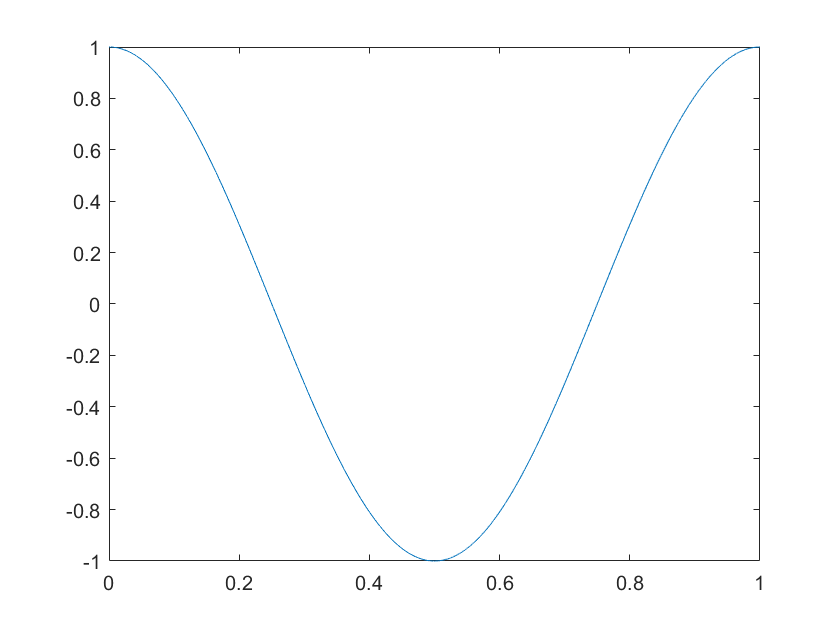

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

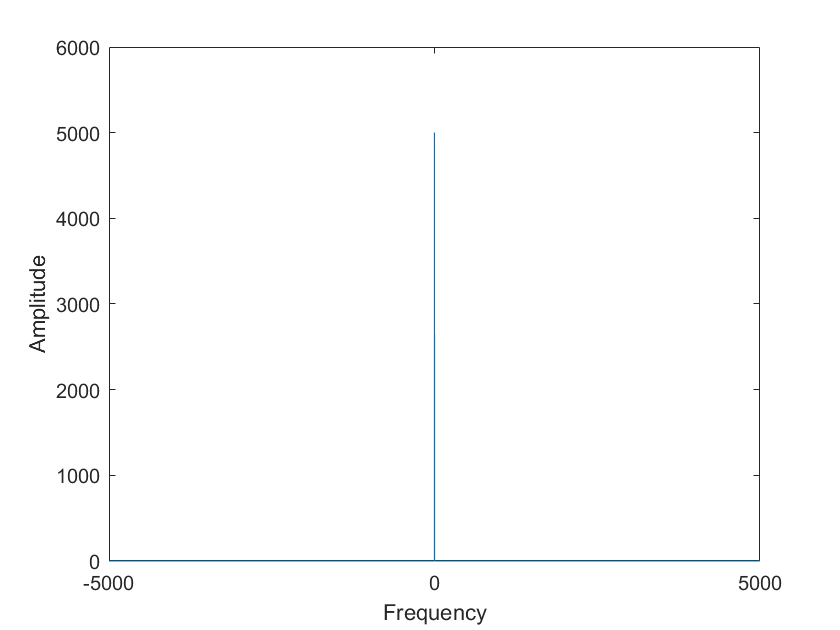

plotF(message, fs);

调制

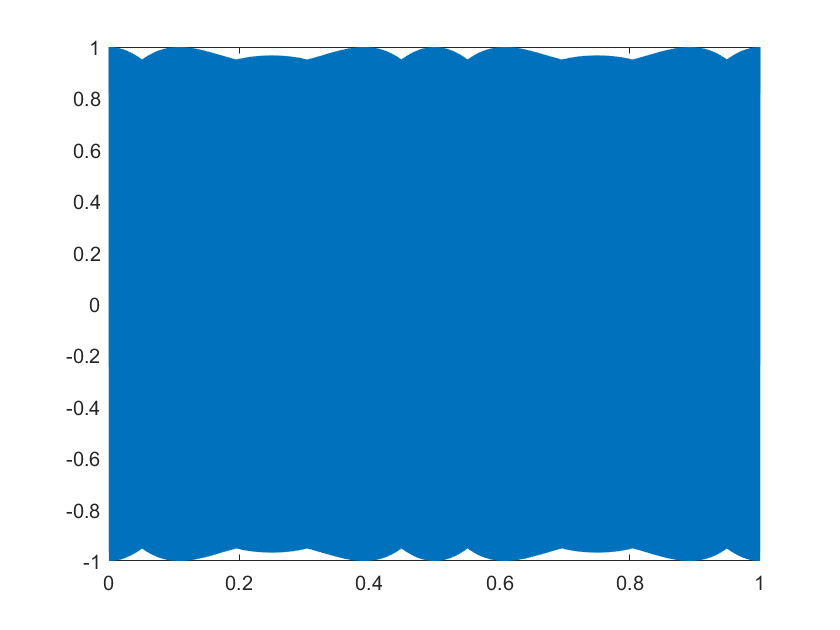

kf = 1;
Ac = 1;
m = cumtrapz(t, message);
modulated = Ac * cos(2*pi*1000*t + 2*pi*kf*m);
plot(t, modulated);

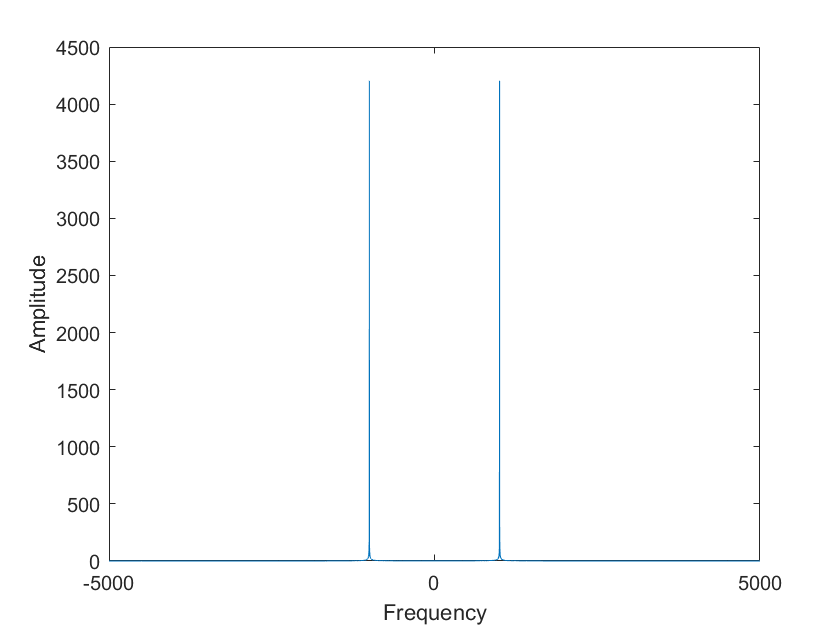

plotF(modulated, fs);

信道

sig_in_channel = modulated;

解调

sig_hilbert = hilbert(sig_in_channel);
phase = unwrap(angle(sig_hilbert)) - 2*pi*1000*t;
f = phase / kf

f =     0.2220    0.0941    0.0286   -0.0194   -0.0461   -0.0483   -0.0339   -0.0081    0.0166    0.0320    0.0356    0.0280    0.0149    0.0011   -0.0085   -0.0107   -0.0054    0.0053    0.0168    0.0252    0.0280    0.0248    0.0179    0.0102    0.0046    0.0033    0.0067    0.0136    0.0213    0.0271    0.0292    0.0274    0.0229    0.0177    0.0138    0.0131    0.0157    0.0208    0.0266    0.0311    0.0330    0.0318    0.0285    0.0246    0.0218    0.0213    0.0235    0.0276    0.0324    0.0361


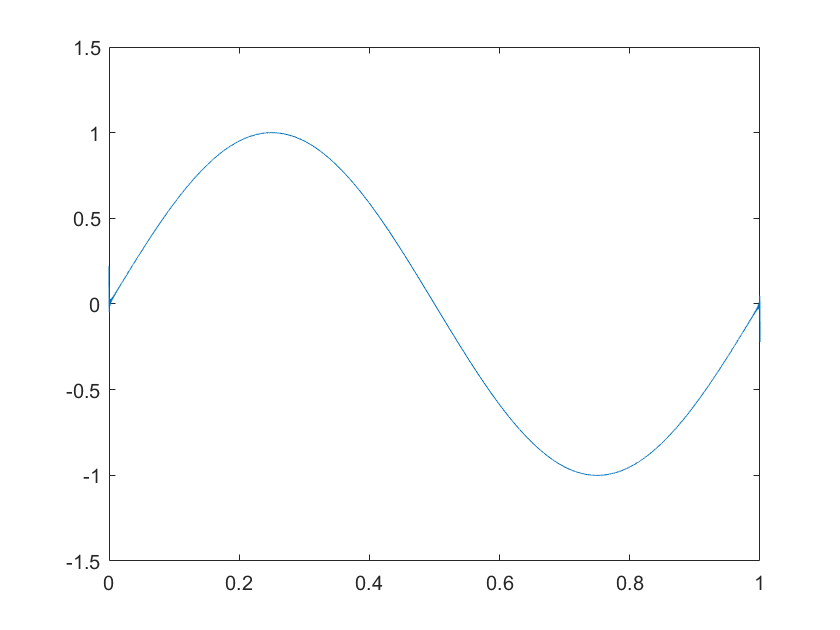

plot(t, f)